## Investigation: does motion influence the correlation between PE and FA?

#### Loading packages we'll need

% Adding packages we need
% For Plotting
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\gramm-master'); 
% For emmeans
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\emmeans');


#### Loading tables containing, PE, FA, and MO

PE = parameter estimates. In this case, these are parameter estimates for regions where white matter structure influences the tDCS-induced changes in brain activity.

FA = our metric for white matter structure. We are evaluating three tracts- whole skeleton (WS), the rAI-dACC/preSMA, or Salience Network tract (SN), and the mPFC-PCC/PRE, or Default Mode Network (DMN) tract.

MO = motion outliers. Our metric are DVARS, though several others may be used as well. 

PEandFA = readtable("PEandFA.xlsx");
MO = table2dataset(readtable("PTandHCMO.csv"));

% The below lines average the DVARs values per participant so they can be
% added to the PE and FA table. Two TBI participants had one fewer session
% than the others, and two healthy control participants had three more DVARs values 
% than the others, so their means were calculated seperately. 

df =[];
for k=1:width(MO)
    if k==5 
        df(:,k) = mean(table2array(dataset2table(MO(1:784,k))));
    elseif k==30
         df(:,k) = mean(table2array(dataset2table(MO(1:784,k))));
    elseif k==43
        df(:,k) = mean(table2array(dataset2table(MO(1:1179,k))));
    elseif k==51
        df(:,k) = mean(table2array(dataset2table(MO(1:1179,k))));
    else
        df(:,k) = mean(table2array(dataset2table(MO(1:1176,k)))); 
    end
end


df = array2table(df');
PEandFA(:,12) = df ;

#### Influence of motion on the relationship between WS FA and tDCS-induced changes in brain activity

% Four WS analysis:
%Columns 1:4 = WS PE
%Column 5 = WS FA

T = table2dataset(PEandFA);

T.Properties.VarNames{1} = 'PE_Wholeskel_cope3';
T.Properties.VarNames{2} = 'PE_Wholeskel_cope5';
T.Properties.VarNames{3} = 'PE_Wholeskel_cope10';
T.Properties.VarNames{4} = 'PE_Wholeskel_cope11';
T.Properties.VarNames{5} = 'FA_WHOLESKEL';

T.Properties.VarNames{6} = 'PE_SN_cope3';
T.Properties.VarNames{7} = 'PE_SN_cope5';
T.Properties.VarNames{8} = 'FA_SN';

T.Properties.VarNames{9} = 'PE_DMN_cope3';
T.Properties.VarNames{10} = 'PE_DMN_cope10';
T.Properties.VarNames{11} = 'FA_DMN';

T.Properties.VarNames{12} = 'MO';
 
% Column 1
lme_light_clean1= fitglme(T,'PE_Wholeskel_cope3 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_Wholeskel_cope3 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    354.49    364.52    -172.24          344.49  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }        -71.255     39.839     -1.7886    51
    {'FA_WHOLESKEL'   }         229.18     127.14      1.8026    51
    {'MO'             }         1.0303     5.8485     0.17617    51
    {'FA_WHOLESKEL:MO'}        -3.6669     18.706    -

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat       DF1    DF2    pValue  
    {'(Intercept)'    }           3.199    1      51     0.079624
    {'FA_WHOLESKEL'   }          3.2494    1      51      0.07736
    {'MO'             }        0.031036    1      51      0.86086
    {'FA_WHOLESKEL:MO'}        0.038429    1      51      0.84536


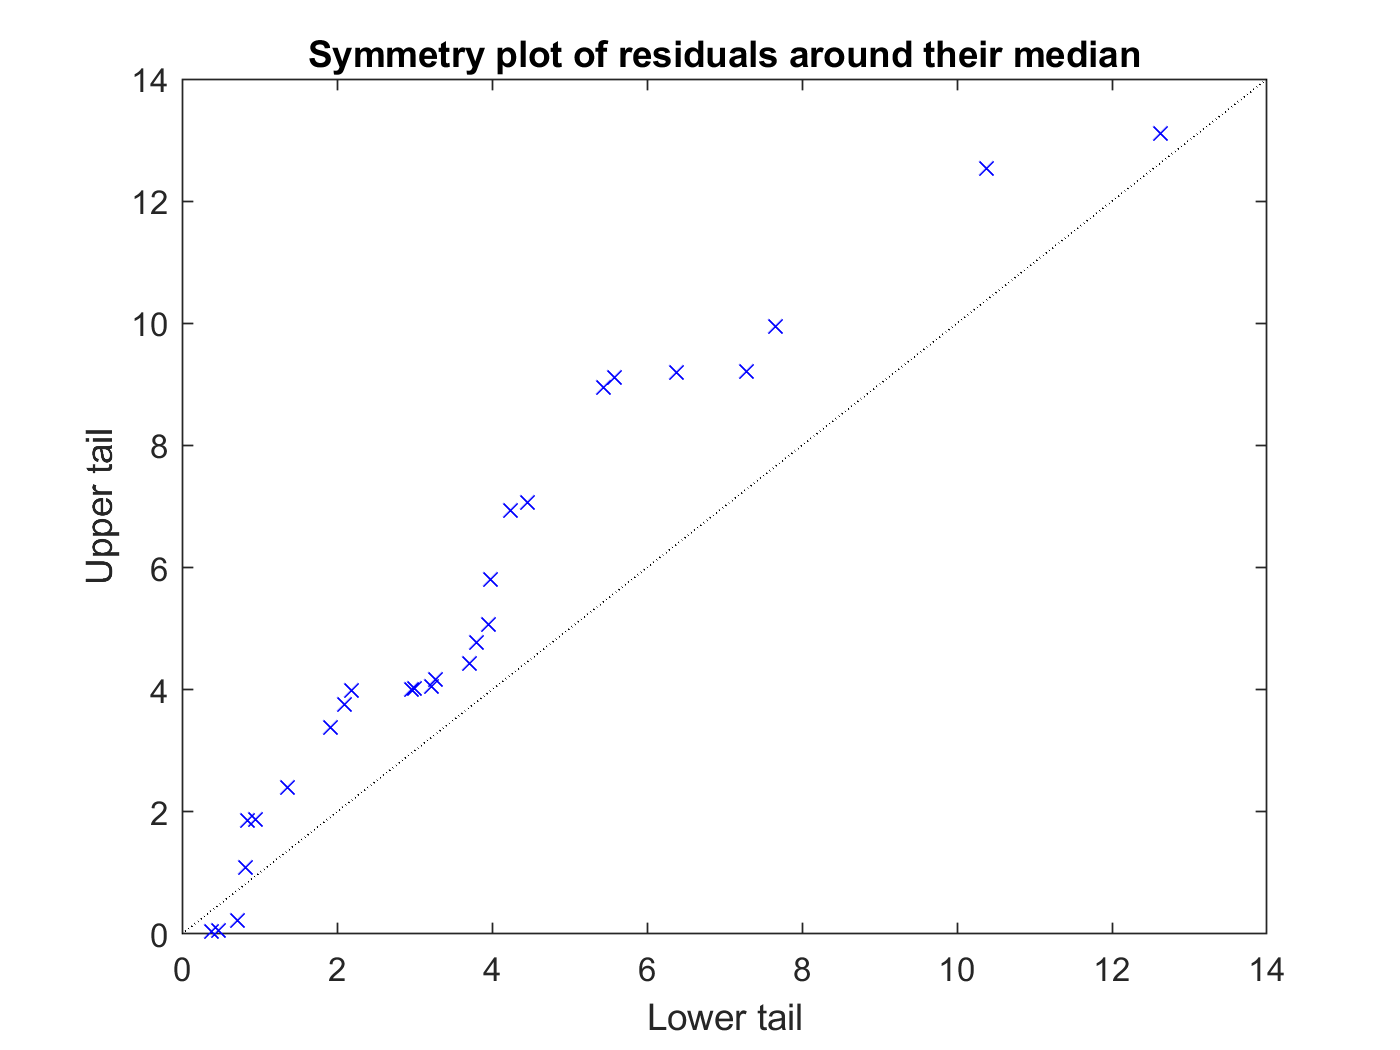

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.8

% Column 2
lme_light_clean1= fitglme(T,'PE_Wholeskel_cope5 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_Wholeskel_cope5 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    393.53    403.57    -191.77          383.53  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }        -61.556     56.815     -1.0834    51
    {'FA_WHOLESKEL'   }         175.29     181.32     0.96677    51
    {'MO'             }        -1.0709     8.3407    -0.12839    51
    {'FA_WHOLESKEL:MO'}         5.9746     26.676     

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat       DF1    DF2    pValue 
    {'(Intercept)'    }          1.1739    1      51     0.28371
    {'FA_WHOLESKEL'   }         0.93464    1      51     0.33822
    {'MO'             }        0.016485    1      51     0.89834
    {'FA_WHOLESKEL:MO'}         0.05016    1      51     0.82368


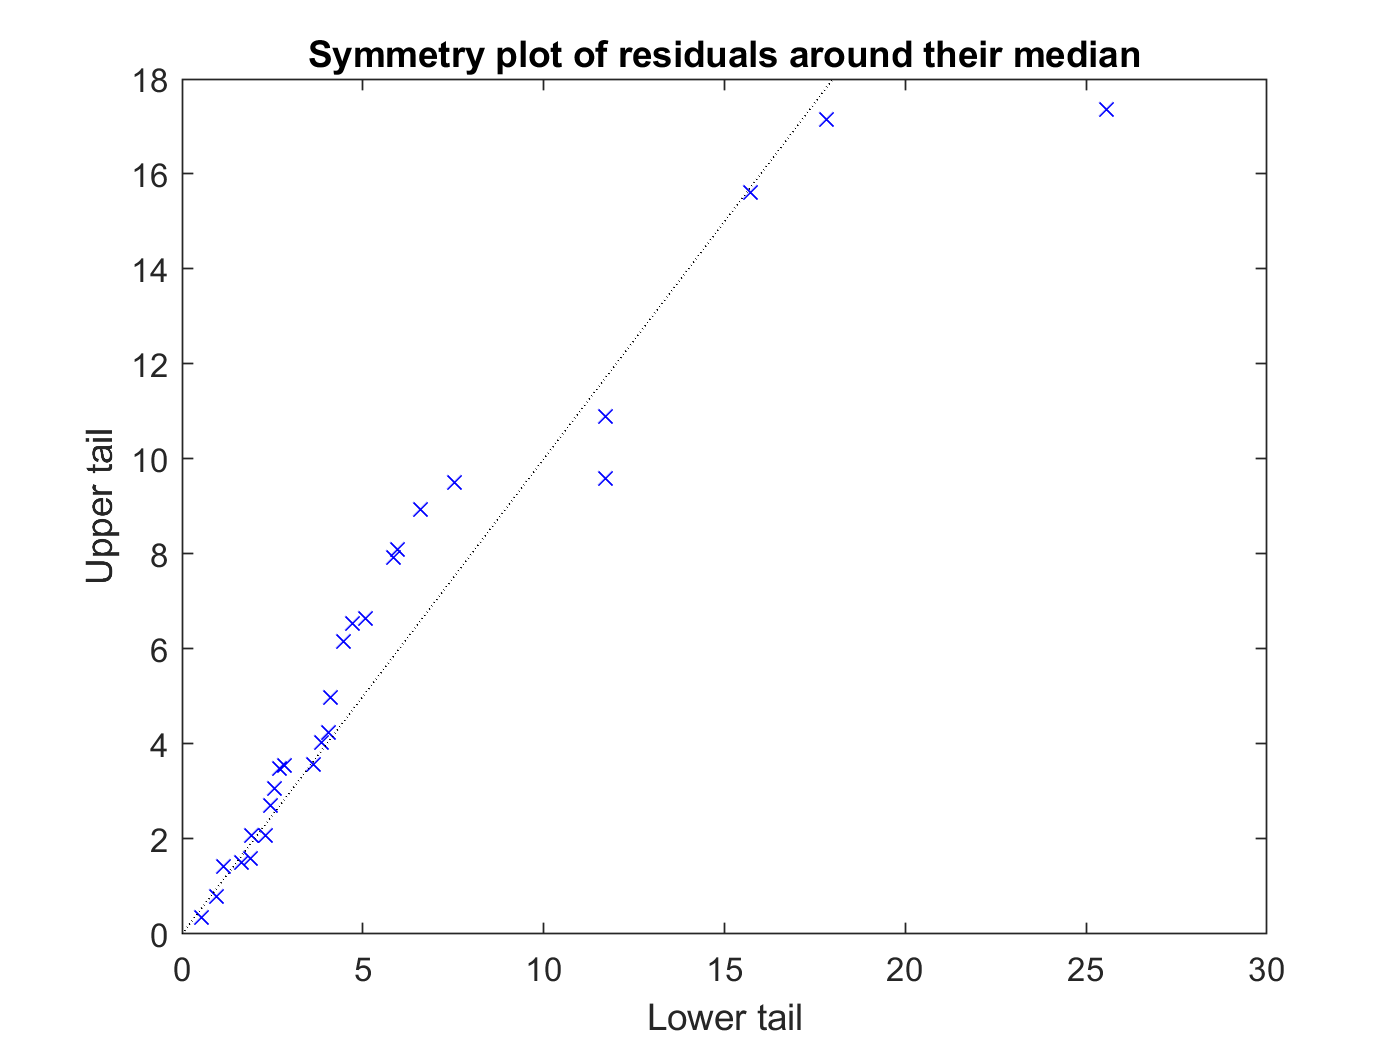

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.8

% Column 3
lme_light_clean1= fitglme(T,'PE_Wholeskel_cope10 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_Wholeskel_cope10 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    415.26    425.3    -202.63          405.26  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }        -46.637     69.225     -0.6737    51
    {'FA_WHOLESKEL'   }          132.9     220.92     0.60159    51
    {'MO'             }        -7.4665     10.163    -0.73471    51
    {'FA_WHOLESKEL:MO'}           25.7     32.503      

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2    pValue 
    {'(Intercept)'    }        0.45387    1      51     0.50354
    {'FA_WHOLESKEL'   }        0.36191    1      51     0.55011
    {'MO'             }         0.5398    1      51     0.46588
    {'FA_WHOLESKEL:MO'}         0.6252    1      51     0.43278


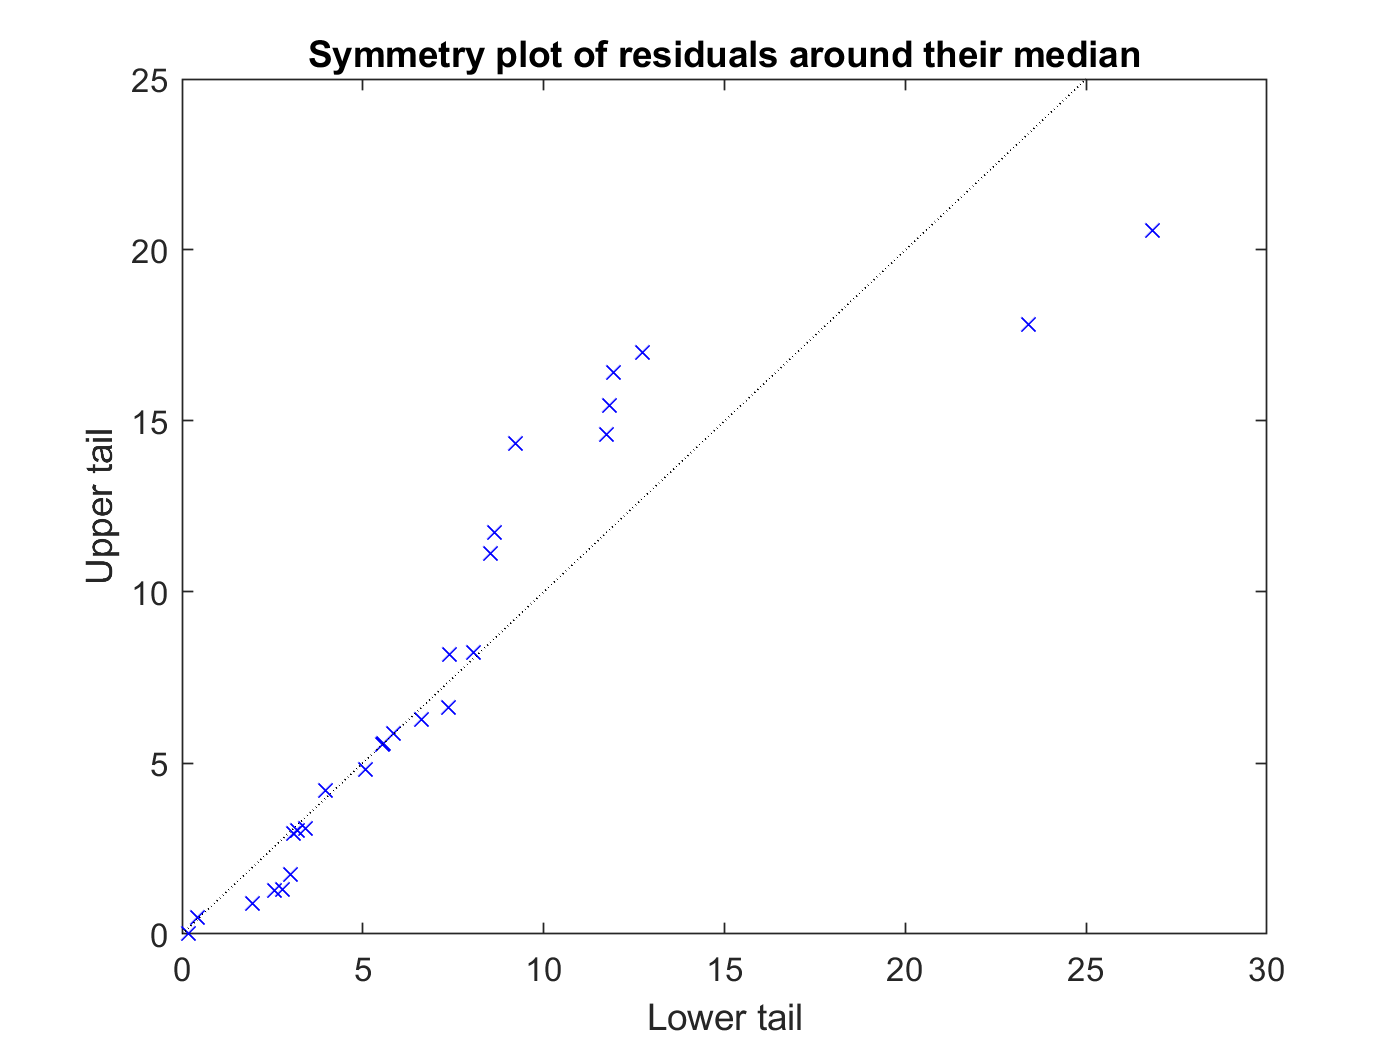

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.4

% Column 4
lme_light_clean1= fitglme(T,'PE_Wholeskel_cope11 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_Wholeskel_cope11 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    422.07    432.11    -206.04          412.07  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat      DF
    {'(Intercept)'    }        -170.92     73.646    -2.3208    51
    {'FA_WHOLESKEL'   }         526.28     235.03     2.2392    51
    {'MO'             }         13.954     10.812     1.2907    51
    {'FA_WHOLESKEL:MO'}        -41.931     34.579    -1.2

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat     DF1    DF2    pValue  
    {'(Intercept)'    }        5.3861    1      51     0.024334
    {'FA_WHOLESKEL'   }        5.0141    1      51      0.02953
    {'MO'             }        1.6659    1      51      0.20263
    {'FA_WHOLESKEL:MO'}        1.4704    1      51      0.23087


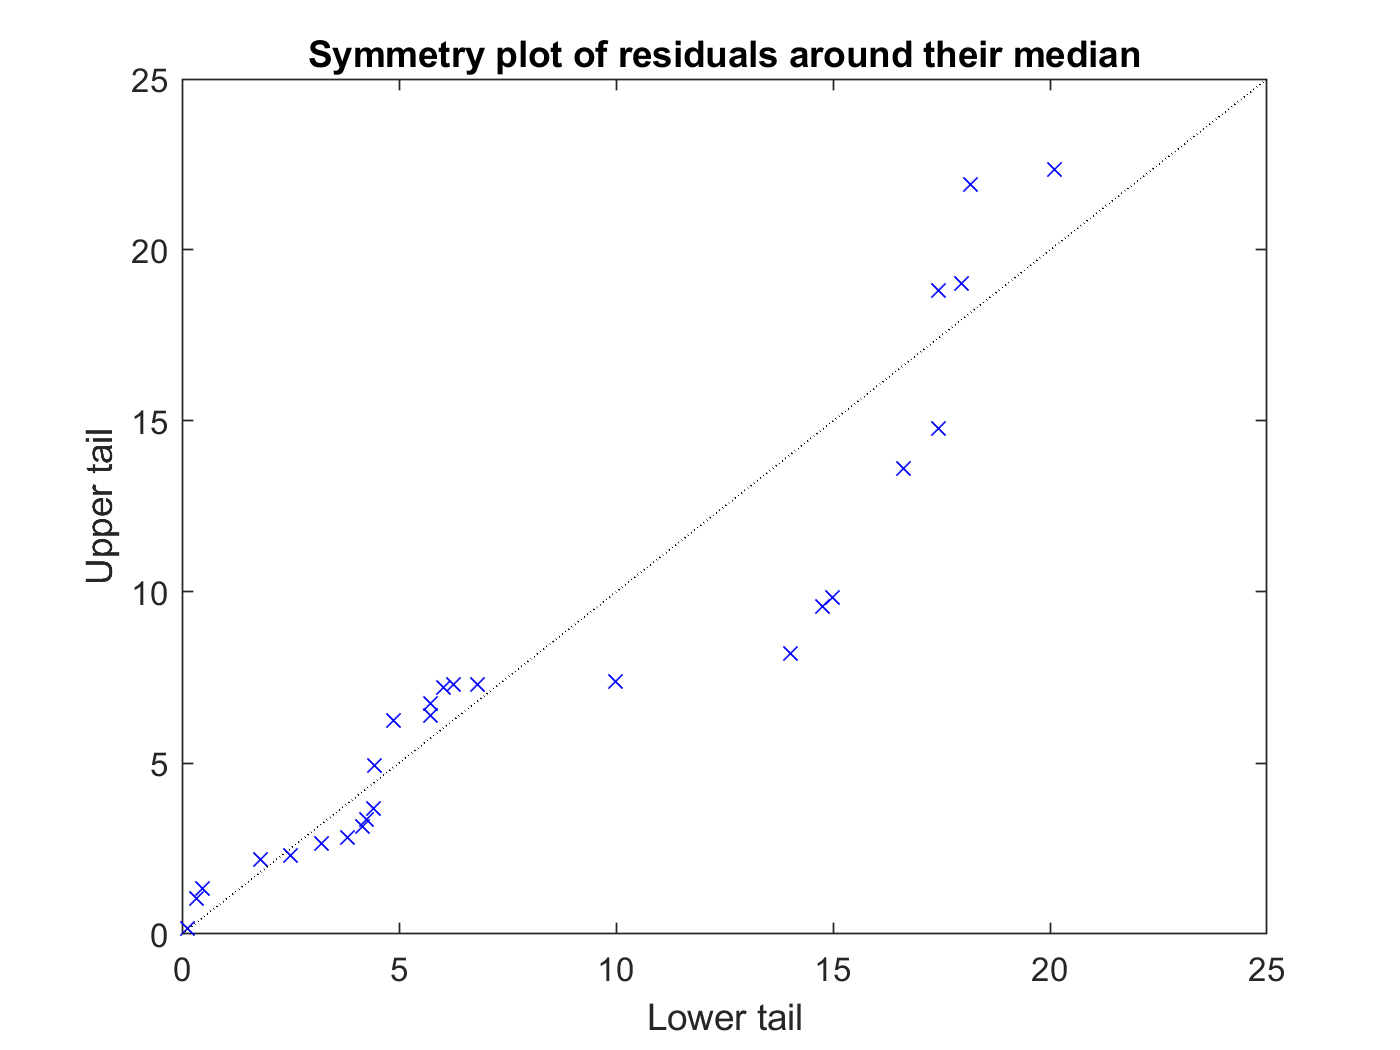

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.2


#### Influence of motion on the relationship between SN FA and tDCS-induced changes in brain activity

% Two SN analysis:
%Column 6:7 = SN PE
%Column 8 = SN FA

% Column 6
lme_light_clean1= fitglme(T,'PE_SN_cope3 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_SN_cope3 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    379.01    389.05    -184.51          369.01  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }        -21.865      49.79    -0.43915    51
    {'FA_WHOLESKEL'   }         87.299     158.89     0.54941    51
    {'MO'             }        -4.8009     7.3093    -0.65682    51
    {'FA_WHOLESKEL:MO'}         13.064     23.378     0.55883

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2    pValue 
    {'(Intercept)'    }        0.19285    1      51     0.66241
    {'FA_WHOLESKEL'   }        0.30185    1      51     0.58512
    {'MO'             }        0.43142    1      51     0.51425
    {'FA_WHOLESKEL:MO'}        0.31229    1      51     0.57872


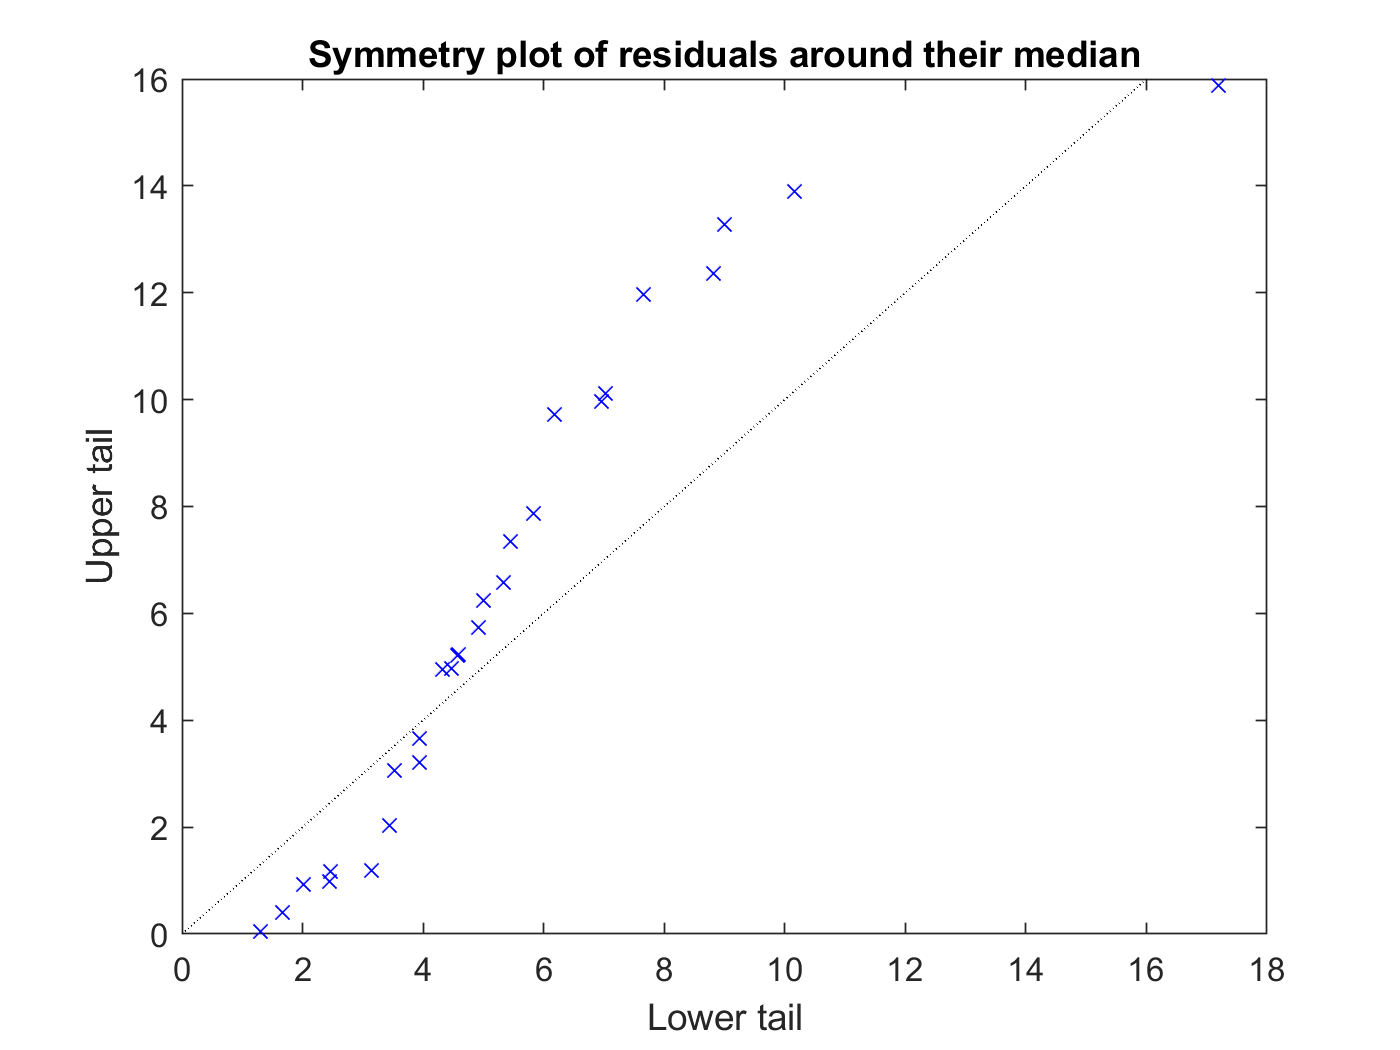

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.6

% Column 7
lme_light_clean1= fitglme(T,'PE_SN_cope5 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_SN_cope5 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    387.97    398.01    -188.98          377.97  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }         46.842     54.014     0.86722    51
    {'FA_WHOLESKEL'   }        -151.04     172.38    -0.87626    51
    {'MO'             }         -10.23     7.9294     -1.2902    51
    {'FA_WHOLESKEL:MO'}         32.065     25.361      1.2643

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2    pValue 
    {'(Intercept)'    }        0.75208    1      51     0.38988
    {'FA_WHOLESKEL'   }        0.76782    1      51       0.385
    {'MO'             }         1.6646    1      51      0.2028
    {'FA_WHOLESKEL:MO'}         1.5985    1      51     0.21186


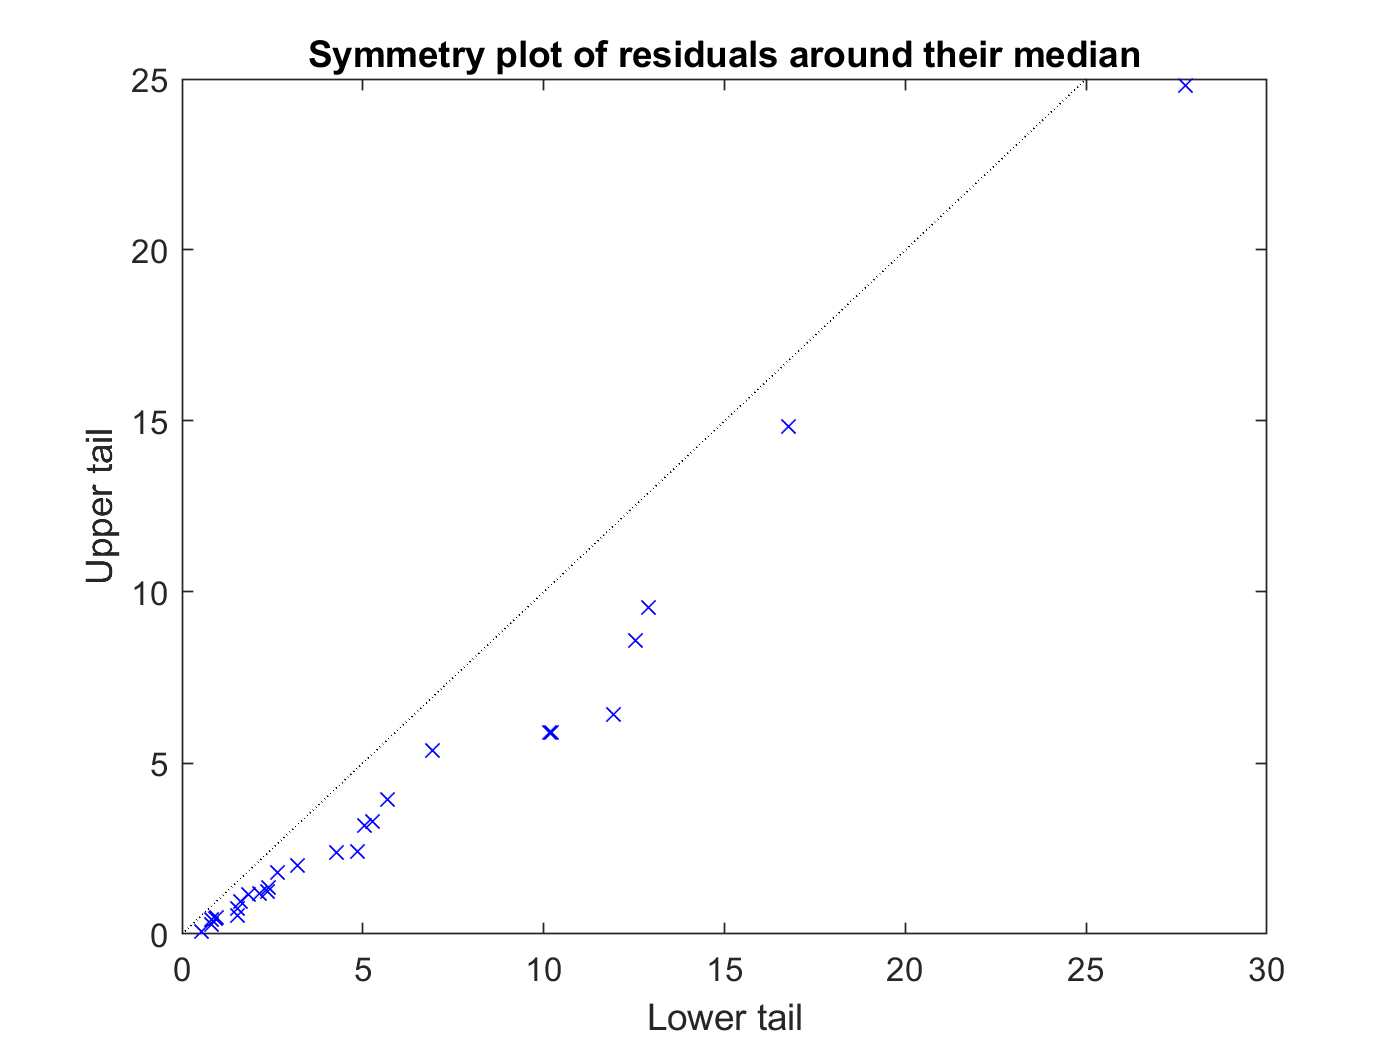

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.2



#### Influence of motion on the relationship between DMN FA and tDCS-induced changes in brain activity

% Two DMN analysis:
%Column 9:10 = DMN PE
%Column 11 = DMN FA

% Column 9
lme_light_clean1= fitglme(T,'PE_DMN_cope3 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_DMN_cope3 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC      BIC       LogLikelihood    Deviance
    383.1    393.14    -186.55          373.1   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }         42.416     51.676     0.82081    51
    {'FA_WHOLESKEL'   }         -114.3     164.91    -0.69307    51
    {'MO'             }        -12.606     7.5862     -1.6617    51
    {'FA_WHOLESKEL:MO'}         37.089     24.263      1.5286 

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2    pValue 
    {'(Intercept)'    }        0.67373    1      51     0.41557
    {'FA_WHOLESKEL'   }        0.48034    1      51     0.49141
    {'MO'             }         2.7612    1      51     0.10271
    {'FA_WHOLESKEL:MO'}         2.3366    1      51     0.13255


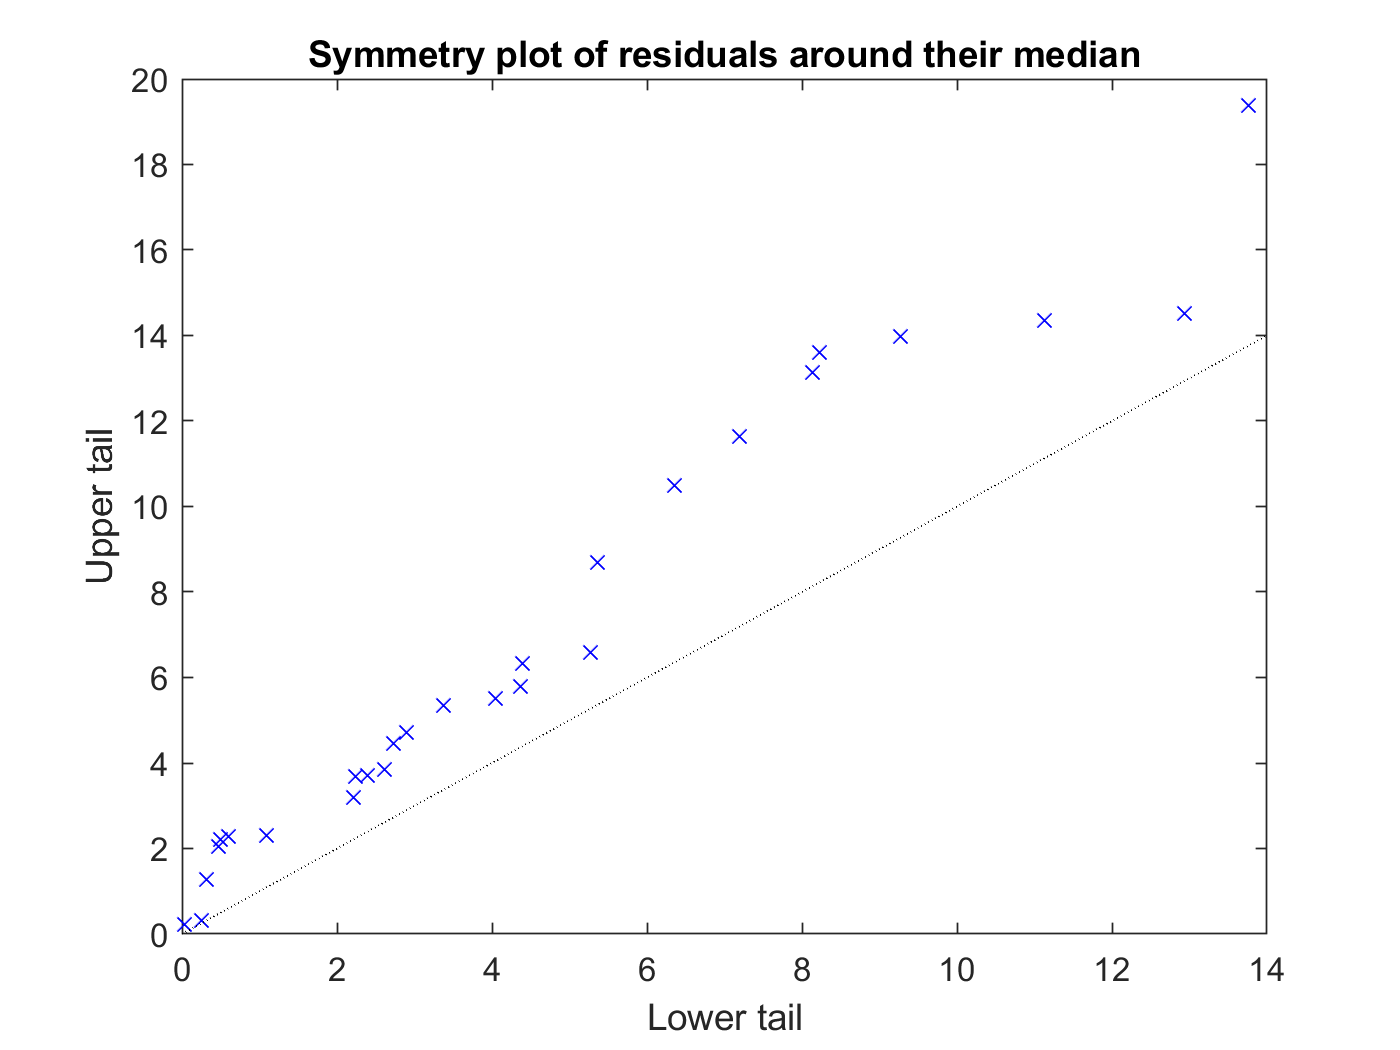

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.1

% Column 10
lme_light_clean1= fitglme(T,'PE_DMN_cope10 ~ MO*FA_WHOLESKEL');
disp(lme_light_clean1)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              55
    Fixed effects coefficients           4
    Random effects coefficients          0
    Covariance parameters                1
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    PE_DMN_cope10 ~ 1 + FA_WHOLESKEL*MO

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    385.35    395.38    -187.67          375.35  

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF
    {'(Intercept)'    }         18.506     52.742     0.35089    51
    {'FA_WHOLESKEL'   }        -62.451     168.32    -0.37103    51
    {'MO'             }        -8.4656     7.7427     -1.0934    51
    {'FA_WHOLESKEL:MO'}         27.124     24.764      1.09

anova(lme_light_clean1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2    pValue 
    {'(Intercept)'    }        0.12312    1      51     0.72712
    {'FA_WHOLESKEL'   }        0.13767    1      51     0.71215
    {'MO'             }         1.1954    1      51     0.27937
    {'FA_WHOLESKEL:MO'}         1.1997    1      51     0.27853


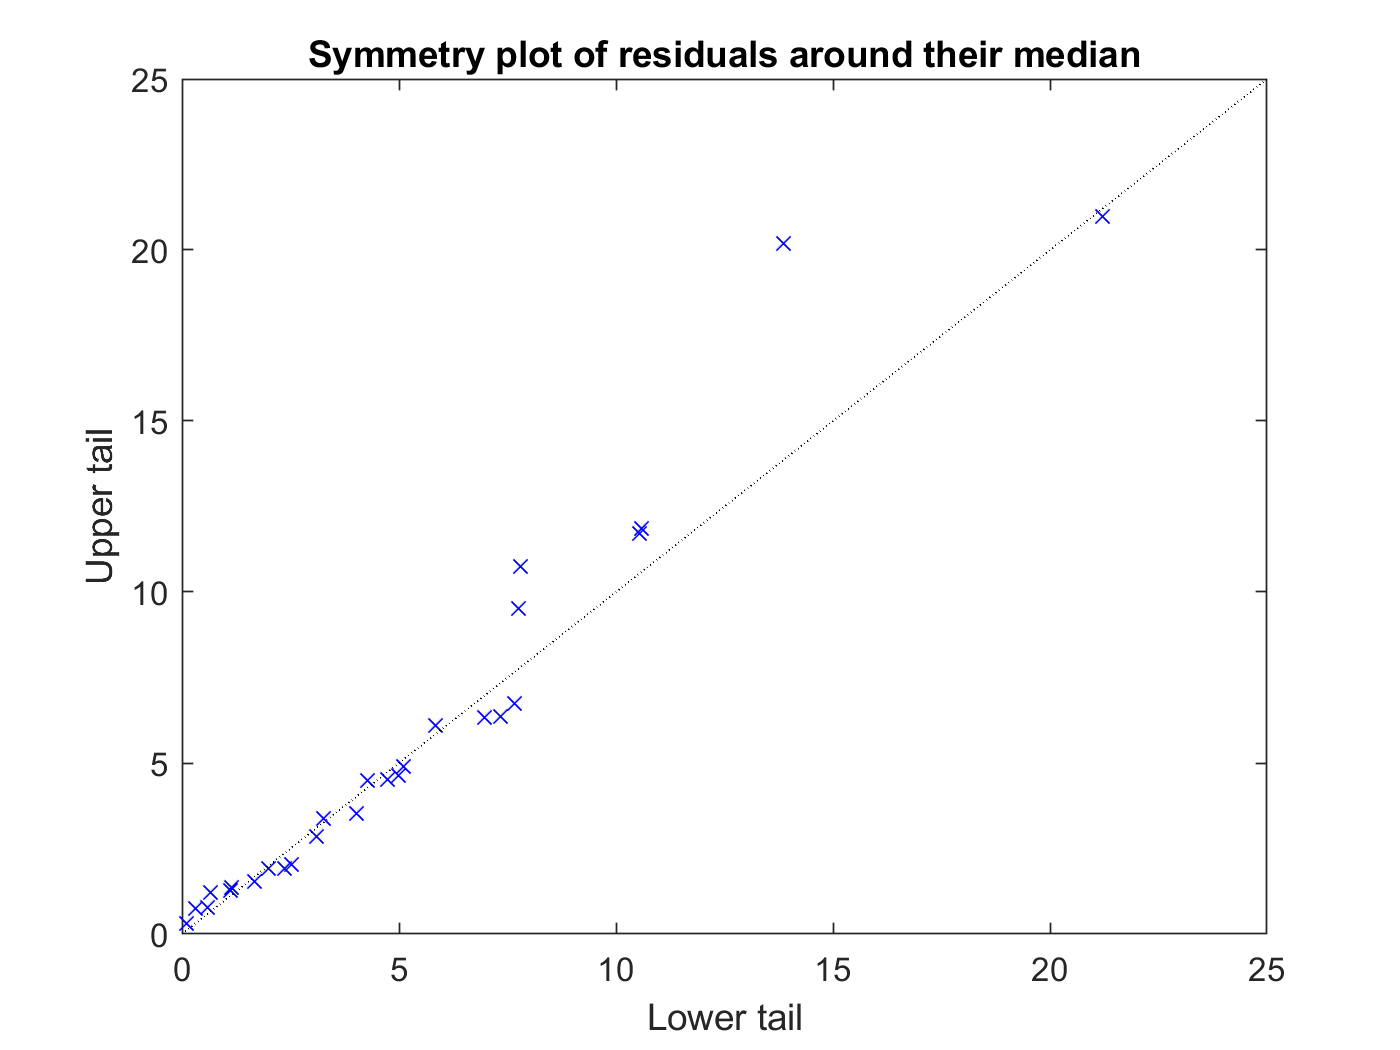

figure
plotResiduals(lme_light_clean1, 'symmetry')

% Interaction p val = 0.3